clear;clc;close('all');

% Constants
e = 1.60217662e-19; % Elementary charge (Coulombs)
a_0 = 5.29177211e-11; % Bohr radius (meters)
h_bar = 1.054571817e-34; % Reduced Planck constant (J·s)
c = 2.998e8; % Speed of light (m/s)

% 1S-2P orbits
tdm = -128*sqrt(2)/243*e*a_0 % Precise transition dipole moment (C·m)

tdm = -6.3158e-30

E_a = -13.6 * e; % Energy of 1S orbit
E_b = -3.4 * e; % Energy of 2P orbit
w=(E_b-E_a)/h_bar

w = 1.5497e+16


% Laser
nu=w*1  % Angular frequency of UV laser (Hz)

nu = 1.5497e+16

I = 10^9; % Laser intensity (W/m²)
eps0 = 8.854e-12; % Vacuum permittivity (F/m)
E_field_amplitude = sqrt(2*I/(eps0*c)) % Electric field amplitude (V/m)

E_field_amplitude = 8.6802e+05


omega_R_0 = abs(tdm) * E_field_amplitude / h_bar

omega_R_0 = 5.1986e+10


% Time array
t = linspace(0, 1e-10, 100)

t = 1.0e-10 *

         0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


dt=t(2)-t(1)

global T % Counter
T=1;

% Hamiltonian H_0 and H_1_base
H_0 = [E_a, 0; 0, E_b]

H_0 = 1.0e-17 *

   -0.2179         0
         0   -0.0545


H_1_base = [0, -tdm*E_field_amplitude; -conj(tdm)*E_field_amplitude, 0]

H_1_base = 1.0e-23 *

         0    0.5482
    0.5482         0


[omega_R, integral_omega_R] = rabi_frequency(t, omega_R_0);

omega_R = 1.0e+10 *

    5.1986
    5.1986
    5.1986
    5.1986
    5.1986
    5.1986
    5.1986
    5.1986
    5.1986
    5.1986


fprintf('transition probability = %6.4f',integral_omega_R);

transition probability = 5.1986

omega_R = 1.0e+10 *

    5.1986
    5.1986
    5.1986
    5.1986
    5.1986
    5.1986
    5.1986
    5.1986
    5.1986
    5.1986


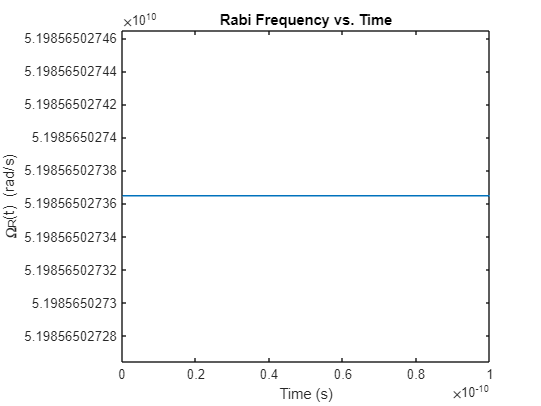

plot_rabi_frequency(t, rabi_frequency(t, omega_R_0));

% Time evolution of Ca_A(t) and Cb_A(t) using the Time-dependent Schrodinger Equation
[Ca_A, Cb_A, t] = analytic_time_evolution(t, w, nu, omega_R_0);

Nabla = 0

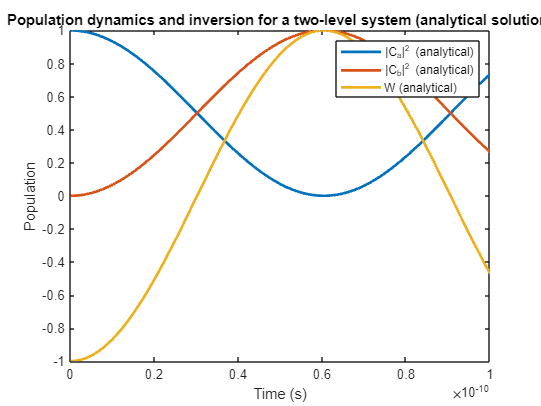

plot_population_analytic(t, Ca_A, Cb_A);

% Time evolution of Ca(t) and Cb(t) using the Time-dependent Schrodinger Equation
tic;
[Ca, Cb, t] = time_evolution(t, H_0, H_1_base, nu);

1.56187e+07 successful steps
0 failed attempts
9.37125e+07 function evaluations


toc;

Elapsed time is 352.447824 seconds.


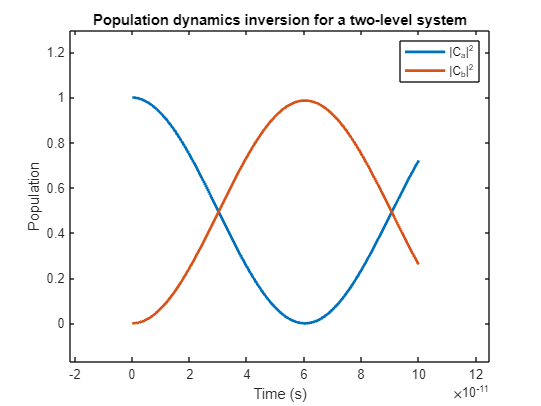

plot_population(t, Ca, Cb);

save(Ca,Cb);

tr = linspace(0, 1e-10, 100000)

tr = 1.0e-10 *

         0    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005


dt=t(2)-t(1)

dt = 1.0101e-12

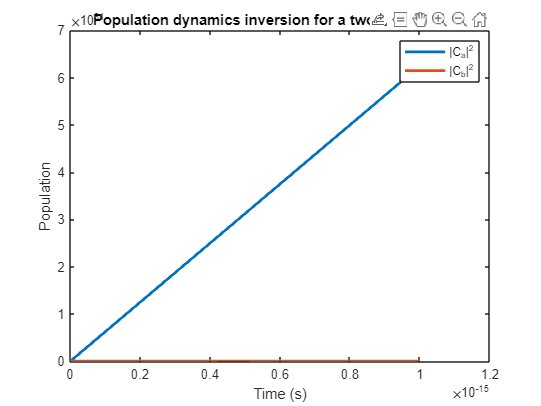

[RCa, RCb] = rk4_time_evolution(tr, dt, H_0, H_1_base, nu);
plot_population(tr, RCa, RCb);

% Transition probability as a function of detuning frequency
delta = linspace(-10*omega_R_0, 10*omega_R_0, 51) % Define the detuning angular frequency array

delta = 1.0e+11 *

   -5.1986   -4.9906   -4.7827   -4.5747   -4.3668   -4.1589   -3.9509   -3.7430   -3.5350   -3.3271   -3.1191   -2.9112   -2.7033   -2.4953   -2.2874   -2.0794   -1.8715   -1.6635   -1.4556   -1.2477   -1.0397   -0.8318   -0.6238   -0.4159   -0.2079         0    0.2079    0.4159    0.6238    0.8318    1.0397    1.2477    1.4556    1.6635    1.8715    2.0794    2.2874    2.4953    2.7033    2.9112    3.1191    3.3271    3.5350    3.7430    3.9509    4.1589    4.3668    4.5747    4.7827    4.9906


t_d=linspace(0, 1e-10, 26) % Redefine t for simplicity

t_d = 1.0e-10 *

         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000


trans_prob = calc_transition_probability(H_0, H_1_base, w, delta, t_d);

     1

     2



create_animation(t_d, delta, trans_prob);

function pulse = gaussian_pulse(t)
    % Gaussian Temporal Pulse
    tau = 6e-11; % Pulse duration (FWHM) in seconds
    t0= 5e-11;
    pulse = 1; % No pulse
    pulse = exp(-(4*log(2)*(t - t0).^2)/tau^2);
end

function [omega_R, integral_omega_R] = rabi_frequency(t, omega_R_0)
    % Rabi frequency
    pulse=gaussian_pulse(t);
    omega_R = omega_R_0 .* (zeros(size(t))+pulse);
    omega_R(:) = omega_R_0

    % Calculate the integral of Rabi frequency
    integral_omega_R = trapz(t, omega_R);
end

function plot_rabi_frequency(t, omega_R)
    figure;
    plot(t, omega_R);
    xlabel('Time (s)');
    ylabel('\Omega_R(t) (rad/s)');
    title('Rabi Frequency vs. Time');
    hold off;
end

function [Ca, Cb] = rk4_time_evolution(t, dt, H_0, H_1_base, nu)
    num_points = length(t);
    h_bar = 1.054571817e-34; % Reduced Planck constant (J·s)

    % Initialize Ca(t) and Cb(t)
    Ca = zeros(num_points, 1);
    Cb = zeros(num_points, 1);

    % Initial conditions
    Ca(1) = 1;
    Cb(1) = 0;

    % Time evolution using the 4th-order Runge-Kutta method
    % for idx = 2:num_points
    %     psi = [Ca(idx-1); Cb(idx-1)];
    % 
    %     H_1_t = H_1_base * cos(nu * t(idx-1));
    %     H_t = H_0 + H_1_t;
    %     k1 = -1i * (H_t * psi) / h_bar;
    % 
    %     H_1_t = H_1_base * cos(nu * (t(idx-1) + 0.5 * dt));
    %     H_t = H_0 + H_1_t;
    %     k2 = -1i * ((H_t * (psi + 0.5 * dt * k1)) / h_bar);
    % 
    %     H_1_t = H_1_base * cos(nu * (t(idx-1) + 0.5 * dt));
    %     H_t = H_0 + H_1_t;
    %     k3 = -1i * ((H_t * (psi + 0.5 * dt * k2)) / h_bar);
    % 
    %     H_1_t = H_1_base * cos(nu * t(idx));
    %     H_t = H_0 + H_1_t;
    %     k4 = -1i * ((H_t * (psi + dt * k3)) / h_bar);
    % 
    %     Ca(idx) = Ca(idx-1) + (1/6)*dt*(k1(1) + 2*k2(1) + 2*k3(1) + k4(1));
    %     Cb(idx) = Cb(idx-1) + (1/6)*dt*(k1(2) + 2*k2(2) + 2*k3(2) + k4(2));
    % end

    for idx = 2:num_points
        H_1_t = H_1_base * cos(nu * t(idx-1));
        H_t = H_0 + H_1_t;

        k1_Ca = -1i * (H_t(1,1) * Ca(idx-1) + H_t(1,2) * Cb(idx-1)) / h_bar;
        k1_Cb = -1i * (H_t(2,1) * Ca(idx-1) + H_t(2,2) * Cb(idx-1)) / h_bar;

        H_1_t = H_1_base * cos(nu * (t(idx-1) + 0.5 * dt));
        H_t = H_0 + H_1_t;

        k2_Ca = -1i * (H_t(1,1) * (Ca(idx-1) + 0.5 * dt * k1_Ca) + H_t(1,2) * (Cb(idx-1) + 0.5 * dt * k1_Cb)) / h_bar;
        k2_Cb = -1i * (H_t(2,1) * (Ca(idx-1) + 0.5 * dt * k1_Ca) + H_t(2,2) * (Cb(idx-1) + 0.5 * dt * k1_Cb)) / h_bar;

        H_1_t = H_1_base * cos(nu * (t(idx-1) + 0.5 * dt));
        H_t = H_0 + H_1_t;

        k3_Ca = -1i * (H_t(1,1) * (Ca(idx-1) + 0.5 * dt * k2_Ca) + H_t(1,2) * (Cb(idx-1) + 0.5 * dt * k2_Cb)) / h_bar;
        k3_Cb = -1i * (H_t(2,1) * (Ca(idx-1) + 0.5 * dt * k2_Ca) + H_t(2,2) * (Cb(idx-1) + 0.5 * dt * k2_Cb)) / h_bar;

        H_1_t = H_1_base * cos(nu * t(idx));
        H_t = H_0 + H_1_t;

        k4_Ca = -1i * (H_t(1,1) * (Ca(idx-1) + dt * k3_Ca) + H_t(1,2) * (Cb(idx-1) + dt * k3_Cb)) / h_bar;
        k4_Cb = -1i * (H_t(2,1) * (Ca(idx-1) + dt * k3_Ca) + H_t(2,2) * (Cb(idx-1) + dt * k3_Cb)) / h_bar;

        Ca(idx) = Ca(idx-1) + (1/6)*dt*(k1_Ca + 2*k2_Ca + 2*k3_Ca + k4_Ca);
        Cb(idx) = Cb(idx-1) + (1/6)*dt*(k1_Cb + 2*k2_Cb + 2*k3_Cb + k4_Cb);
    end
end



function dPsi = hamiltonian(t, Psi, H_0, H_1_base, nu, h_bar)
    %H_1_t = H_1_base * cos(nu * t) .* gaussian_pulse([t]);
    H_1_t = H_1_base * cos(nu * t);
    H_t = H_0 + H_1_t;
    
    global T; %For monitoring
    if t>T*1e-11
        
        disp([T t]);
        T=T+1;
    end
    
    dPsi = -(1i/h_bar) * H_t * Psi;
end

function [Ca, Cb, t] = time_evolution(t, H_0, H_1_base, nu)
    h_bar = 1.054571817e-34; % Reduced Planck constant (J·s)

    % Initial conditions
    Psi0 = [1; 0];

    % Time evolution using ode45
    options = odeset('RelTol', 1e-7, 'AbsTol', 1e-10, 'Stats','on');
    [t_out, Psi_out] = ode45(@(t, Psi) hamiltonian(t, Psi, H_0, H_1_base, nu, h_bar), t, Psi0, options);

    % Extract Ca(t) and Cb(t)
    Ca = Psi_out(:, 1);
    Cb = Psi_out(:, 2);
    t = t_out;
end

function plot_population(t, Ca, Cb)
    figure;
    plot(t, abs(Ca).^2, 'LineWidth', 2);
    hold on;
    plot(t, abs(Cb).^2, 'LineWidth', 2);
    
    % W = abs(Cb).^2 - abs(Ca).^2;
    % plot(t, W, 'LineWidth', 2);
    
    hold off;
    xlabel('Time (s)');
    ylabel('Population');
    legend('|C_a|^2', '|C_b|^2');
    title('Population dynamics inversion for a two-level system');
end

function [Ca_A, Cb_A, t_out] = analytic_time_evolution(t, w, nu, omega_R_0)
    num_points = length(t);

    % Initial conditions
    Ca_A_0 = 1;
    Cb_A_0 = 0;

    % Define Nabla
    Nabla = w - nu

    % Calculate Rabi frequency Omega_R
    Omega_R = omega_R_0;

    % Calculate Omega
    Omega = sqrt(Omega_R^2 + Nabla^2);

    t_out = t;

    % Calculate Ca_A(t) and Cb_A(t) for each time point
    Ca_A = zeros(num_points, 1);
    Cb_A = zeros(num_points, 1);
    for i = 1:num_points
        ti = t(i);
        Ca_A(i) = (Ca_A_0 * (cos(Omega * ti / 2) - 1i * Nabla / Omega * sin(Omega * ti / 2)) + 1i * Omega_R / Omega * Cb_A_0 * sin(Omega * ti / 2)) * exp(1i * Nabla * ti / 2);
        Cb_A(i) = (Cb_A_0 * (cos(Omega * ti / 2) + 1i * Nabla / Omega * sin(Omega * ti / 2)) - 1i * Omega_R / Omega * Ca_A_0 * sin(Omega * ti / 2)) * exp(-1i * Nabla * ti / 2);
    end
end

function plot_population_analytic(t, Ca_A, Cb_A)
    figure;
    plot(t, abs(Ca_A).^2, 'LineWidth', 2);
    hold on;
    plot(t, abs(Cb_A).^2, 'LineWidth', 2);
    
    W_A = abs(Cb_A).^2 - abs(Ca_A).^2;
    plot(t, W_A, 'LineWidth', 2);
    
    hold off;
    xlabel('Time (s)');
    ylabel('Population');
    legend('|C_a|^2 (analytical)', '|C_b|^2 (analytical)', 'W (analytical)');
    title('Population dynamics and inversion for a two-level system (analytical solution)');
end

function save(Ca,Cb)
    data = [real(Ca), imag(Ca), real(Cb), imag(Cb)];
    csvwrite('data.csv', data);
end

function trans_prob = calc_transition_probability(H_0, H_1_base, w, delta, t)
    % Initialize the transition probability matrix
    trans_prob = zeros(length(t), length(delta));

    for i = 1:length(delta)
        % Calculate Ca and Cb for each detuning frequency using time_evolution
        [Ca, Cb, t_out] = time_evolution(t, H_0, H_1_base, delta(i)+w);
        disp(i);
        % Calculate the transition probability |Cb|^2 for each time point
        for j = 1:length(t)
            trans_prob(j, i) = abs(Cb(j))^2;
        end
    end
end

function create_animation(t, delta, trans_prob)
    figure;

    % Define the number of interpolation points
    num_interp_points = 10;

    % Interpolate time and transition probability data
    t_interp = linspace(t(1), t(end), length(t) * num_interp_points);
    trans_prob_interp = interp1(t, trans_prob, t_interp, 'pchip');

    % Create the animation
    for i = 1:length(t_interp)
        plot(delta, trans_prob_interp(i,:));
        hold on;
        axis([delta(1) delta(end) 0 1]);
        xlabel('Detuning Frequency');
        ylabel('Probability');
        title('Transition Probability as a function of detuning frequency');
        pause(0.01); % Adjust the pause time for desired animation speed
        hold off;
    end
end